clc
clear
close all

System and parameters are described

G = tf(1,[1000 500], 'InputDelay', 0.7)

G =
 
                     1
  exp(-0.7*s) * ------------
                1000 s + 500
 
Continuous-time transfer function.



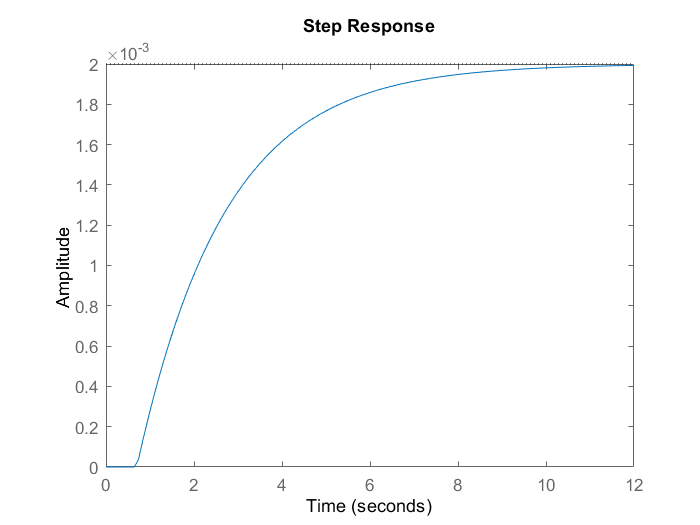


step(G)

stepinfo(step(G))

ans = struct with fields:
        RiseTime: 46.9022
    SettlingTime: 89.4151
     SettlingMin: 0.0018
     SettlingMax: 0.0020
       Overshoot: 0
      Undershoot: 0
            Peak: 0.0020
        PeakTime: 127



syms t
A = 2e-3

A = 0.0020

L = 0.7

L = 0.7000

tau = 2.8

tau = 2.8000

R = A/tau

R = 7.1429e-04

## P-Control loop

### Gain is estimated using Ziegler-Nichols Tuning

Kp = 1/(R*L)

Kp = 2000


H = (Kp*G)/(1+G*Kp)

H =
 
  A = 
         x1    x2    x3
   x1  -0.5     0     2
   x2     0  -0.5     2
   x3     0     1     1
 
  B = 
       u1
   x1   0
   x2   0
   x3  -1
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
  E = 
       x1  x2  x3
   x1   1   0   0
   x2   0   1   0
   x3   0   0   0
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 0.7  0.7 
 
Continuous-time state-space model.



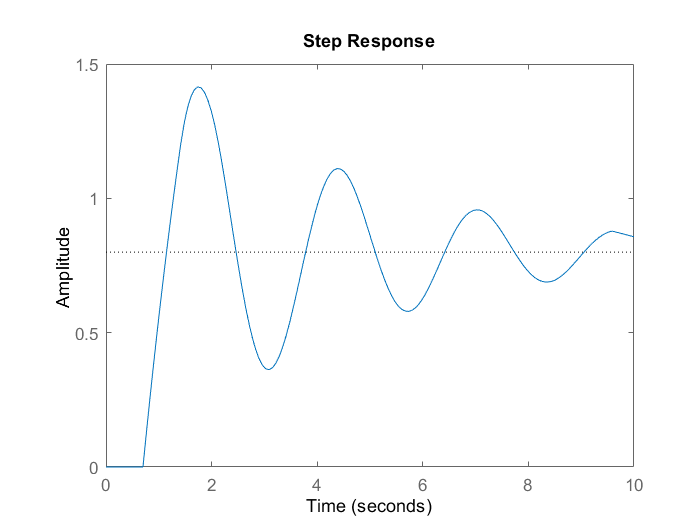


step(H, 10)

### Then a gain with a resulting overshoot of <2% is found

Kp = 500

Kp = 500


H = (Kp*G)/(1+G*Kp)

H =
 
  A = 
         x1    x2    x3
   x1  -0.5     0   0.5
   x2     0  -0.5   0.5
   x3     0     1     1
 
  B = 
       u1
   x1   0
   x2   0
   x3  -1
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
  E = 
       x1  x2  x3
   x1   1   0   0
   x2   0   1   0
   x3   0   0   0
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 0.7  0.7 
 
Continuous-time state-space model.



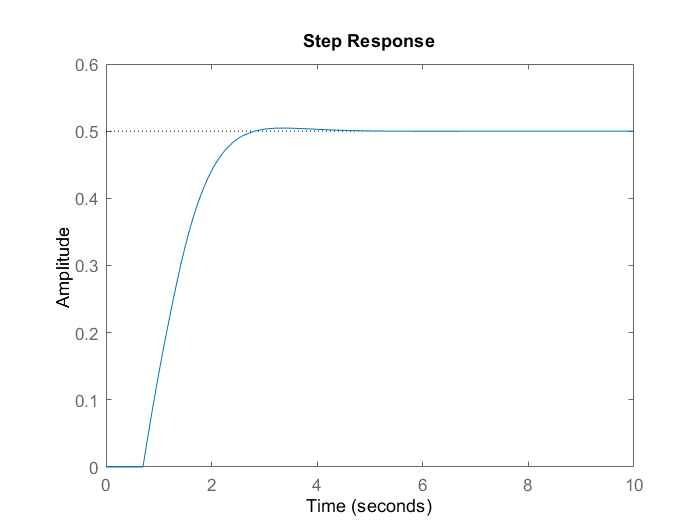


step(H, 10)

## PI-Control loop

### Initial gain and integration time constant is estimated using Ziegler-Nichols Tuning

Kp = 0.9/(R*L)

Kp = 1800


Ti = L/0.3

Ti = 2.3333


s = tf('s')

s =
 
  s
 
Continuous-time transfer function.




K = Kp*(1+Ti*s)/(Ti*s)

K =
 
  4200 s + 1800
  -------------
     2.333 s
 
Continuous-time transfer function.



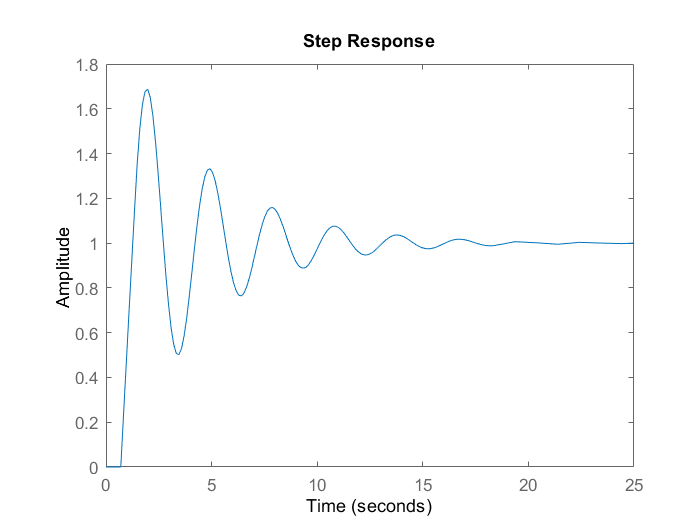


H = (K*G)/(1+G*K);

step(H)

### Then Kp and Ti are tuned to reach the performance specifications, being a 5%-settling time below 3s

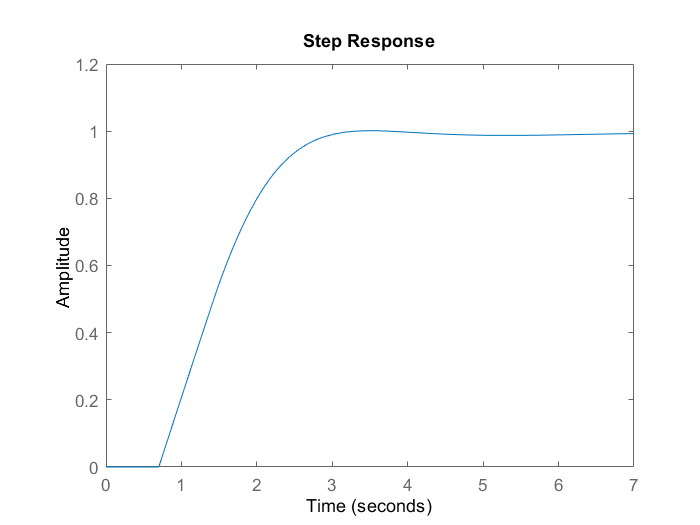

Kp = 695;

Ti = 2.3333;

s = tf('s');

%Ki = Kp/Ti;
Ki = 320;

K = Kp + Ki*1/s;

H = (G*K)/(1+G*K);

step(H, 7)

function G = sym2tf(g, d)
% This function makes a transfer function from a symbolic one
    [n,m]=size(g);
    for i=1:n
        for j=1:m
            [num,den]=numden(g(i,j));
            num_n=sym2poly(num);
            den_n=sym2poly(den);
            G(i,j)=tf(num_n,den_n, 'InputDelay', d);
        end
    end
end